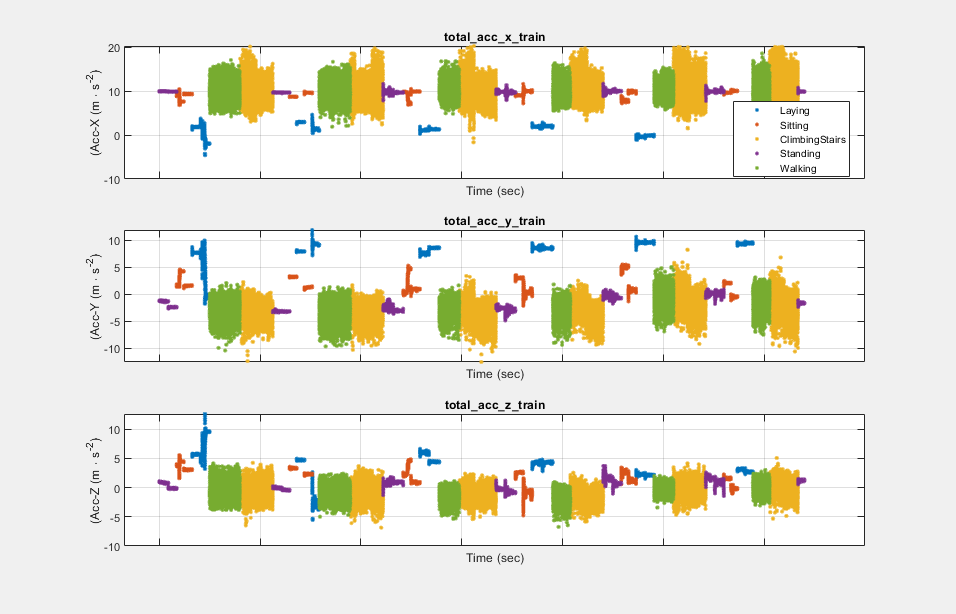

%% Load Test Data
load('rawSensorData_train.mat')

%% Display data summary
plotRawSensorData(total_acc_x_train, total_acc_y_train, ...
    total_acc_z_train,trainActivity,1000)


%% Create Table variable
rawSensorDataTrain = table(...
    total_acc_x_train, total_acc_y_train, total_acc_z_train, ...
    body_gyro_x_train, body_gyro_y_train, body_gyro_z_train);

% Pre-process Training Data: *Feature Extraction*
% Lets start with a simple preprocessing technique. Since the raw sensor 
% data contain fixed-width sliding windows of 2.56sec (128 readings/window) 
T_mean = varfun(@Wmean, rawSensorDataTrain); %avg of boydy_gro_x_train in the time frame (1 row across) for each trial (7352 total  - going down entries)
T_stdv = varfun(@Wstd,rawSensorDataTrain);
T_pca  = varfun(@Wpca1,rawSensorDataTrain);
%%
humanActivityData = [T_mean, T_stdv, T_pca];
humanActivityData.activity = trainActivity;

twoClassHumanActivityData = humanActivityData(humanActivityData.activity=="ClimbingStairs" | humanActivityData.activity=="Walking", :); 

%% Train a model and assess its performance using Classification Learner
classificationLearner